## ode45 implementation with own odefunction

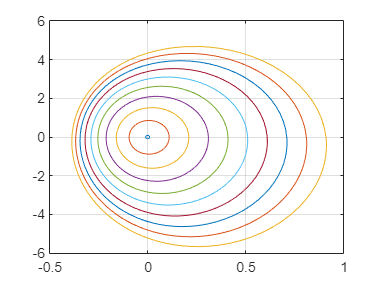

global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;

acc=0.00001; ti=0;
y0=0;
h=0.01;
j=1;
T=[];

for i=setdiff(1:10:100,0)
    x0 = i*h;
    [Te, XY]= ode45cycles(ti,x0,y0,acc,1);
    x2(j)=XY(1,1);
    xdif(j)=XY(end,1)-XY(1,1);
    T(j)=Te(end);
    j=j+1;
    plot(XY(:,1),XY(:,2));
    hold on
end
grid on
hold off

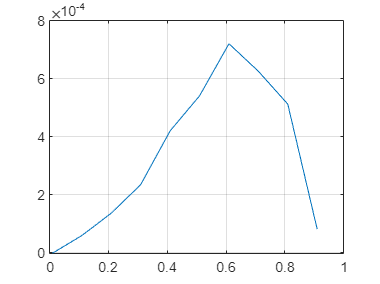


plot(x2,xdif);
grid on

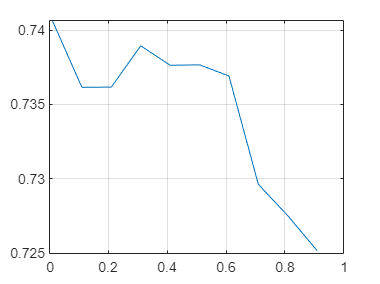


plot(x2,T);
grid on

## Functions

function dfdt=odefcn(T,XY)
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dfdt = zeros(2,1);
    dxdt=@(x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    dfdt(1)=dxdt(XY(1),XY(2));
    dfdt(2)=dydt(XY(1),XY(2));

end

function [T,XY]=ode45cycles(ti,x0,y0,acc,n)
    options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
    tf=ti+10;
    k=1+2*n;
    [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=3;
    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        tf=tf+100;
        [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end
    if(count==cmax)
        ci=y_sign_change(3)+1;
        disp("can't find number of cycles")
        T=T(1:ci);
        XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
end